clear
clc

% Die MATLAB Deep Learning Toolbox stellt einige Funktionen zum Arbeiten mit
% tiefen neuronalen Netzen zur Verfügung.

baseFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(baseFolder)

datenFolder = baseFolder + "\09_Trainingsdaten\AusgeschnittenFürTraining\99_Trainingsdatensätze\01_3Kat30_ohne_30empfehlung";

imdsSchilder = imageDatastore(datenFolder, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");

countEachLabel(imdsSchilder)

ans = 3×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder                408 
    Geschwindigkeitsbegrenzung_30     402 
    Geschwindigkeitsempfehlung_30     591 



numPerLabel = min(countEachLabel(imdsSchilder).Count);
allLabels = unique(imdsSchilder.Labels);
classNames = categories(imdsSchilder.Labels);

numRuns = 10;

% Ergebnisvariablen für Excel-Ausgabe
RunNr = zeros(numRuns,1);
TrainAccuracy = zeros(numRuns,1);
ValidationAccuracy = zeros(numRuns,1);
GesamtAccuracy = zeros(numRuns,1);
AnzahlFalschTrain = zeros(numRuns,1);
AnzahlFalschValidation = zeros(numRuns,1);
AnzahlFalschGesamt = zeros(numRuns,1);

for run = 1:numRuns

    fprintf("\n=====================================\n");
    fprintf("START LAUF %d von %d\n", run, numRuns);
    fprintf("=====================================\n");

    % Jeder Lauf bekommt anderen, aber reproduzierbaren Zufall
    rng(run, "twister")

    %% Balancing neu erzeugen
    balancedFiles = [];

    for i = 1:numel(allLabels)
        label = allLabels(i);

        idx = find(imdsSchilder.Labels == label);

        if numel(idx) >= numPerLabel
            selectedIdx = randsample(idx, numPerLabel);
            balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
        else
            warning("Label '%s' hat weniger als %d Bilder.", string(label), numPerLabel);
        end
    end

    % Neuen ImageDatastore mit ausgewählten Dateien erstellen
    balancedDS = imageDatastore(balancedFiles, ...
        'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
        fullfile(datenFolder, '\'), filesep))));

    %% Train-/Validation-Split neu erzeugen
    [imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");

    %% Netzwerk definieren
    % GAP-Variante
    layers = [
        imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")

        convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
        reluLayer("Name", "relu_1")
        maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_1")

        convolution2dLayer(3, 16, 'Padding', 'same', "Name", "conv_2")
        reluLayer("Name", "relu_2")
        maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_2")

        convolution2dLayer(1, 3, "Name", "conv_3")
        globalAveragePooling2dLayer("Name", "gap")
        softmaxLayer("Name", "softmax")
    ];

    %% Augmented Datastores
    augTrain = augmentedImageDatastore([48 48 3], imdsTrain, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    aug2 = augmentedImageDatastore([48 48 3], imdsSchilder, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    %% Trainingsparameter
    options = trainingOptions('adam', ...
        'MaxEpochs', 100, ...
        "InitialLearnRate", 0.0005, ...
        'MiniBatchSize', 32, ...
        'Shuffle', 'every-epoch', ...
        Plots="training-progress", ...
        Metrics="accuracy", ...
        ValidationData=augVal, ...
        ValidationFrequency=60, ...
        Verbose=true, ...
    VerboseFrequency=50);

    %% Training
    fprintf("Training Lauf %d startet...\n", run);

    [net, info] = trainnet(augTrain, layers, "crossentropy", options);
    T = info.TrainingHistory;
    writetable(T, sprintf("TrainingHistoryGAP10032_Lauf_%02d.xlsx", run));
    % Netz und Trainingsinfo je Lauf speichern
    % save(sprintf("netGAP32_Lauf_%02d.mat", run), "net", "info");

    fprintf("Training Lauf %d beendet.\n", run);

    %% Schätzung Trainingsdatensatz
    tbl = readall(augTrain);
    imgs = tbl{:,1};

    TTrain = imdsTrain.Labels;
    classNamesTrain = categories(TTrain);

    XTrain = cat(4, imgs{:});
    XTrain = single(XTrain);

    outputsTrain = minibatchpredict(net, XTrain);
    YTrain = onehotdecode(squeeze(outputsTrain)', classNamesTrain, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Training", run));
    confusionchart(TTrain, YTrain);
    title(sprintf("Lauf %02d - Training", run));

    confMatTrain = confusionmat(TTrain, YTrain);
    accuracyTrain = sum(diag(confMatTrain)) / sum(confMatTrain(:));
    fprintf('Lauf %d - Training Accuracy: %.2f%%\n', run, accuracyTrain * 100);

    %% Schätzung Validierungsdatensatz
    tbl = readall(augVal);
    imgs = tbl{:,1};

    TTest = imdsValidation.Labels;
    classNamesTest = categories(TTest);

    XTest = cat(4, imgs{:});
    XTest = single(XTest);

    outputsTest = minibatchpredict(net, XTest);
    YTest = onehotdecode(squeeze(outputsTest)', classNamesTest, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Validation", run));
    confusionchart(TTest, YTest);
    title(sprintf("Lauf %02d - Validation", run));

    confMatVal = confusionmat(TTest, YTest);
    accuracyVal = sum(diag(confMatVal)) / sum(confMatVal(:));
    fprintf('Lauf %d - Validation Accuracy: %.2f%%\n', run, accuracyVal * 100);

    %% Schätzung Gesamtbestand
    tbl = readall(aug2);
    imgs = tbl{:,1};

    TTest2 = imdsSchilder.Labels;

    XTest2 = cat(4, imgs{:});
    XTest2 = single(XTest2);

    outputsTest2 = minibatchpredict(net, XTest2);
    YTest2 = onehotdecode(squeeze(outputsTest2)', classNames, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Gesamtbestand", run));
    confusionchart(TTest2, YTest2);
    title(sprintf("Lauf %02d - Gesamtbestand", run));

    confMatAll = confusionmat(TTest2, YTest2);
    accuracyAll = sum(diag(confMatAll)) / sum(confMatAll(:));
    fprintf('Lauf %d - Gesamt Accuracy: %.2f%%\n', run, accuracyAll * 100);

    %% Falsche Ergebnisse ausgeben
    trueLabelsTrain = imdsTrain.Labels;
    trueLabelsVali = imdsValidation.Labels;
    trueLabelsVali2 = imdsSchilder.Labels;

    wrongIdxtrain = find(YTrain ~= trueLabelsTrain);
    wrongIdxVali = find(YTest ~= trueLabelsVali);
    wrongIdxVali2 = find(YTest2 ~= trueLabelsVali2);

    fprintf("Lauf %d - Falsch Training: %d\n", run, numel(wrongIdxtrain));
    fprintf("Lauf %d - Falsch Validation: %d\n", run, numel(wrongIdxVali));
    fprintf("Lauf %d - Falsch Gesamtbestand: %d\n", run, numel(wrongIdxVali2));

## ** Falsch erkannte bilder anzeigen**

START LAUF 1 von 10


Training Lauf 1 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                             10.54                                    33.333
            1        1       00:00:00       0.0005          8.4462                                46.875                      
           50        2       00:00:05       0.0005         0.83884                                59.375                      
           60        2       00:00:06       0.0005           1.172           0.97928              53.125                    60
          100        4       00:00:08       0.0005          1.0195                                 56.25                      
          120        4       00:00:09       0.0005         0.84128            0.8433              53.125       

Training Lauf 1 beendet.


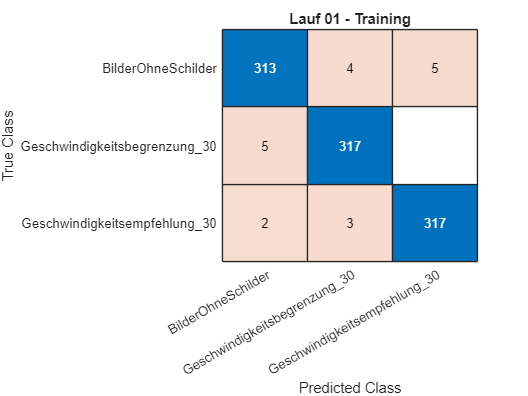

Lauf 1 - Training Accuracy: 98.03%


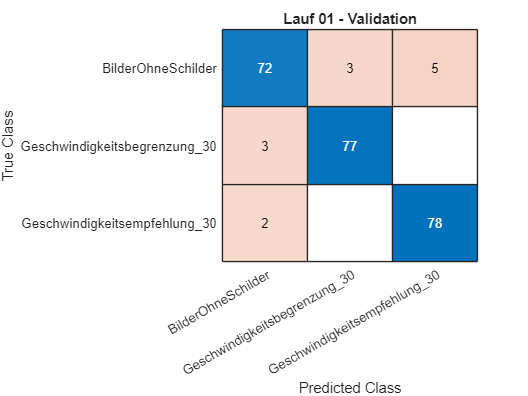

Lauf 1 - Validation Accuracy: 94.58%


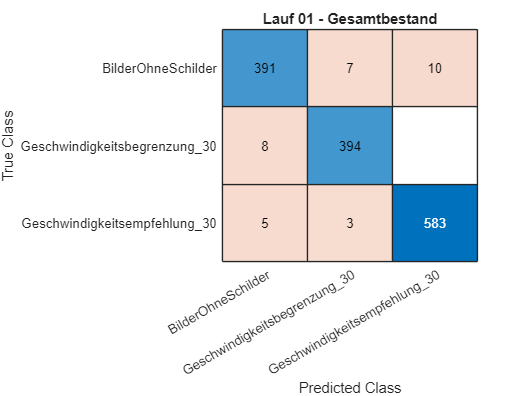

Lauf 1 - Gesamt Accuracy: 97.64%


Lauf 1 - Falsch Training: 19


Lauf 1 - Falsch Validation: 13


Lauf 1 - Falsch Gesamtbestand: 33


ENDE LAUF 1 von 10


START LAUF 2 von 10


Training Lauf 2 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.628                                    33.333
            1        1       00:00:00       0.0005          10.462                                34.375                      
           50        2       00:00:05       0.0005         0.95835                                  62.5                      
           60        2       00:00:05       0.0005         0.95648            1.1029              46.875                55.417
          100        4       00:00:07       0.0005         0.68423                                 68.75                      
          120        4       00:00:08       0.0005         0.55613           0.89717               81.25       

Training Lauf 2 beendet.


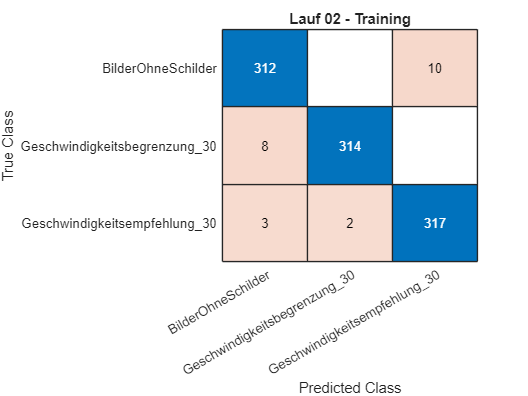

Lauf 2 - Training Accuracy: 97.62%


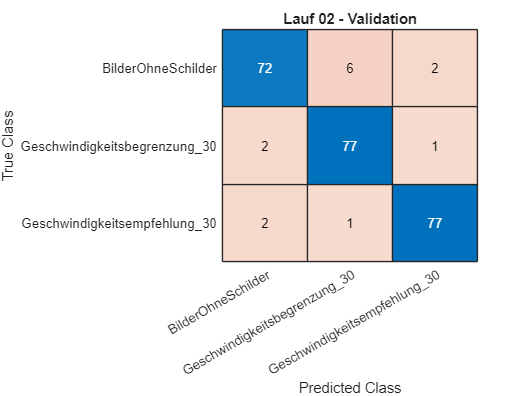

Lauf 2 - Validation Accuracy: 94.17%


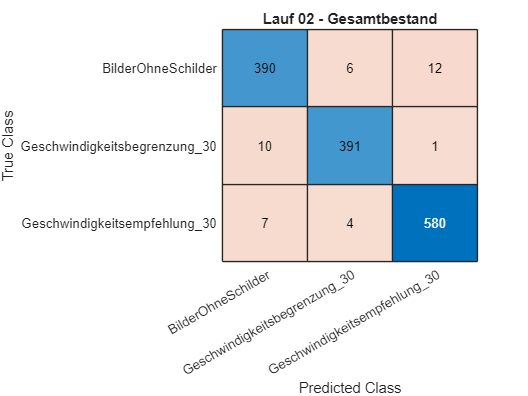

Lauf 2 - Gesamt Accuracy: 97.14%


Lauf 2 - Falsch Training: 23


Lauf 2 - Falsch Validation: 14


Lauf 2 - Falsch Gesamtbestand: 40


ENDE LAUF 2 von 10


START LAUF 3 von 10


Training Lauf 3 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.628                                    33.333
            1        1       00:00:00       0.0005          9.4658                                40.625                      
           50        2       00:00:04       0.0005          2.7207                                28.125                      
           60        2       00:00:05       0.0005          1.3876            1.8222              53.125                48.333
          100        4       00:00:07       0.0005          1.3014                                59.375                      
          120        4       00:00:08       0.0005         0.88268            1.0411                62.5       

Training Lauf 3 beendet.


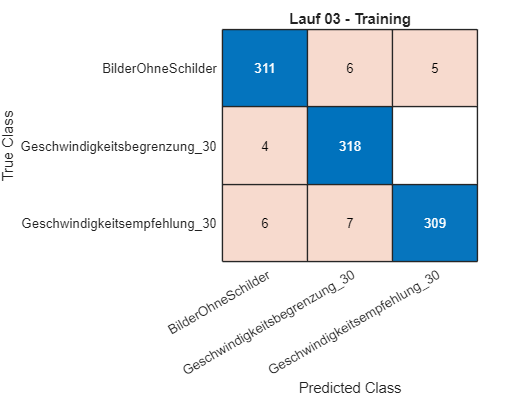

Lauf 3 - Training Accuracy: 97.10%


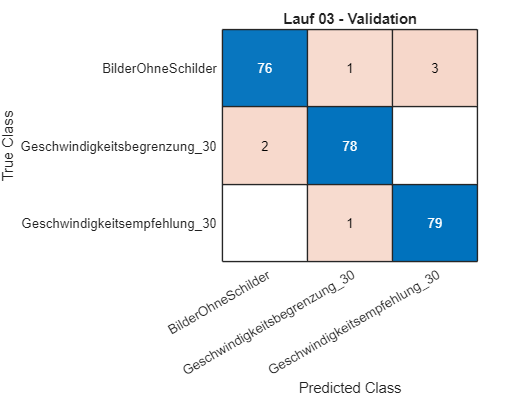

Lauf 3 - Validation Accuracy: 97.08%


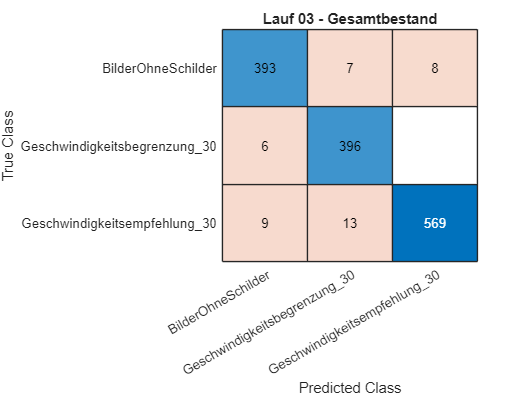

Lauf 3 - Gesamt Accuracy: 96.93%


Lauf 3 - Falsch Training: 28


Lauf 3 - Falsch Validation: 7


Lauf 3 - Falsch Gesamtbestand: 43


ENDE LAUF 3 von 10


START LAUF 4 von 10


Training Lauf 4 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            3.7581                                    30.833
            1        1       00:00:00       0.0005          4.0405                                 31.25                      
           50        2       00:00:04       0.0005         0.79925                                71.875                      
           60        2       00:00:05       0.0005         0.94176           0.83913               56.25                63.333
          100        4       00:00:07       0.0005          0.6763                                 68.75                      
          120        4       00:00:09       0.0005         0.52288            0.6662              78.125       

Training Lauf 4 beendet.


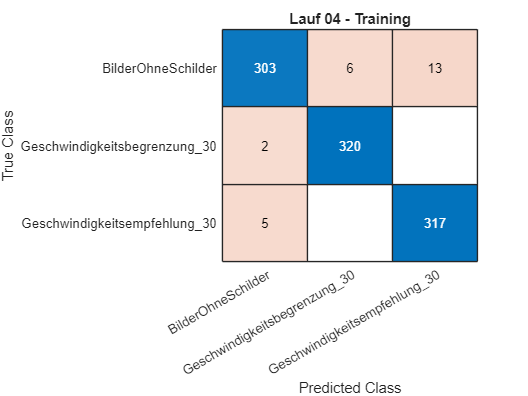

Lauf 4 - Training Accuracy: 97.31%


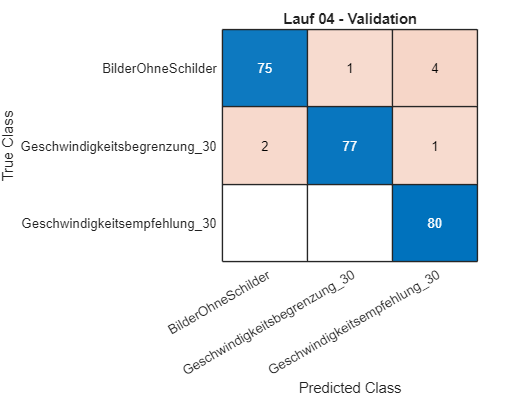

Lauf 4 - Validation Accuracy: 96.67%


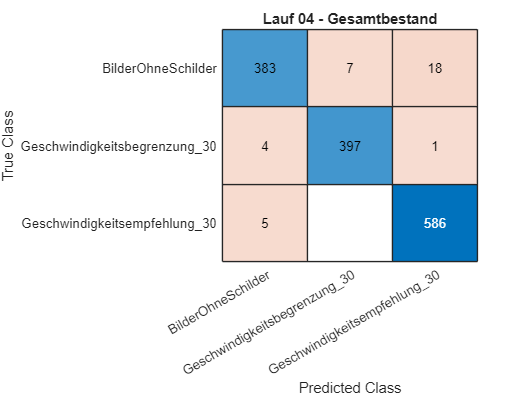

Lauf 4 - Gesamt Accuracy: 97.50%


Lauf 4 - Falsch Training: 26


Lauf 4 - Falsch Validation: 8


Lauf 4 - Falsch Gesamtbestand: 35


ENDE LAUF 4 von 10


START LAUF 5 von 10


Training Lauf 5 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.628                                    33.333
            1        1       00:00:00       0.0005          13.451                                15.625                      
           50        2       00:00:04       0.0005           2.495                                15.625                      
           60        2       00:00:05       0.0005          1.4959             1.675              28.125                  32.5
          100        4       00:00:07       0.0005          1.0698                                 56.25                      
          120        4       00:00:09       0.0005           1.251           0.93667              40.625       

Training Lauf 5 beendet.


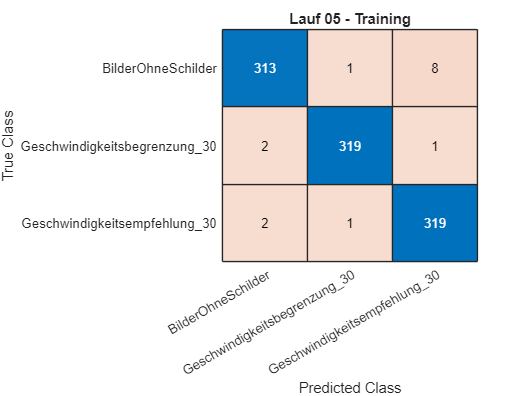

Lauf 5 - Training Accuracy: 98.45%


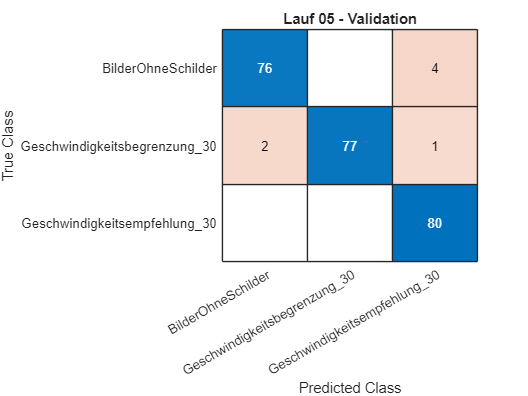

Lauf 5 - Validation Accuracy: 97.08%


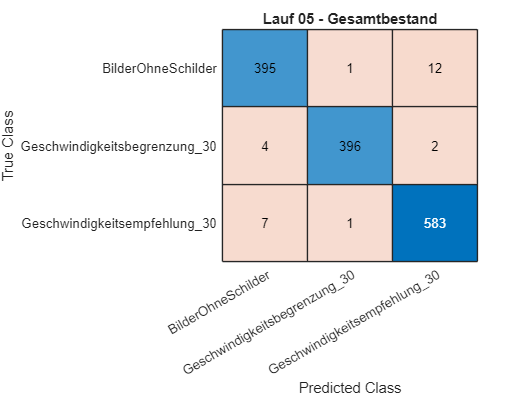

Lauf 5 - Gesamt Accuracy: 98.07%


Lauf 5 - Falsch Training: 15


Lauf 5 - Falsch Validation: 7


Lauf 5 - Falsch Gesamtbestand: 27


ENDE LAUF 5 von 10


START LAUF 6 von 10


Training Lauf 6 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                             8.605                                    33.333
            1        1       00:00:00       0.0005          8.7697                                  37.5                      
           50        2       00:00:05       0.0005          1.0971                                    75                      
           60        2       00:00:05       0.0005          2.1833            2.0048               56.25                 58.75
          100        4       00:00:07       0.0005          1.7898                                40.625                      
          120        4       00:00:09       0.0005          2.0445            2.0076              46.875       

Training Lauf 6 beendet.


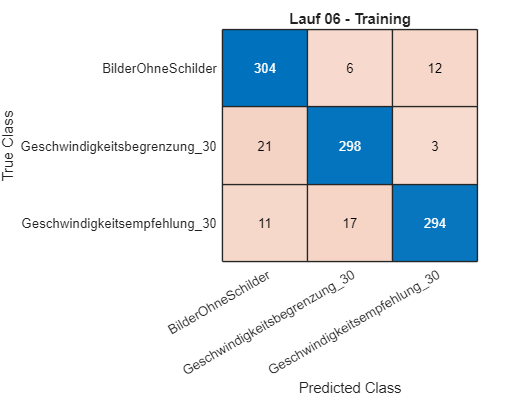

Lauf 6 - Training Accuracy: 92.75%


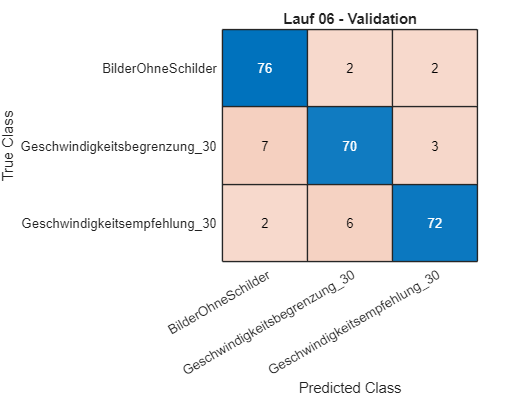

Lauf 6 - Validation Accuracy: 90.83%


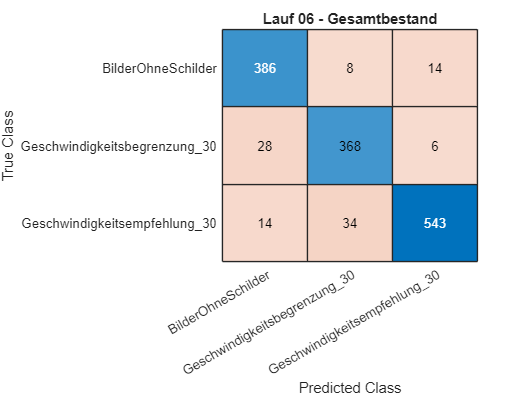

Lauf 6 - Gesamt Accuracy: 92.58%


Lauf 6 - Falsch Training: 70


Lauf 6 - Falsch Validation: 22


Lauf 6 - Falsch Gesamtbestand: 104


ENDE LAUF 6 von 10


START LAUF 7 von 10


Training Lauf 7 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            9.4687                                     33.75
            1        1       00:00:00       0.0005          7.6026                                46.875                      
           50        2       00:00:05       0.0005          2.3025                                 43.75                      
           60        2       00:00:05       0.0005          0.6387            1.8328              78.125                58.333
          100        4       00:00:08       0.0005         0.91468                                  62.5                      
          120        4       00:00:09       0.0005         0.75313            1.3284               68.75       

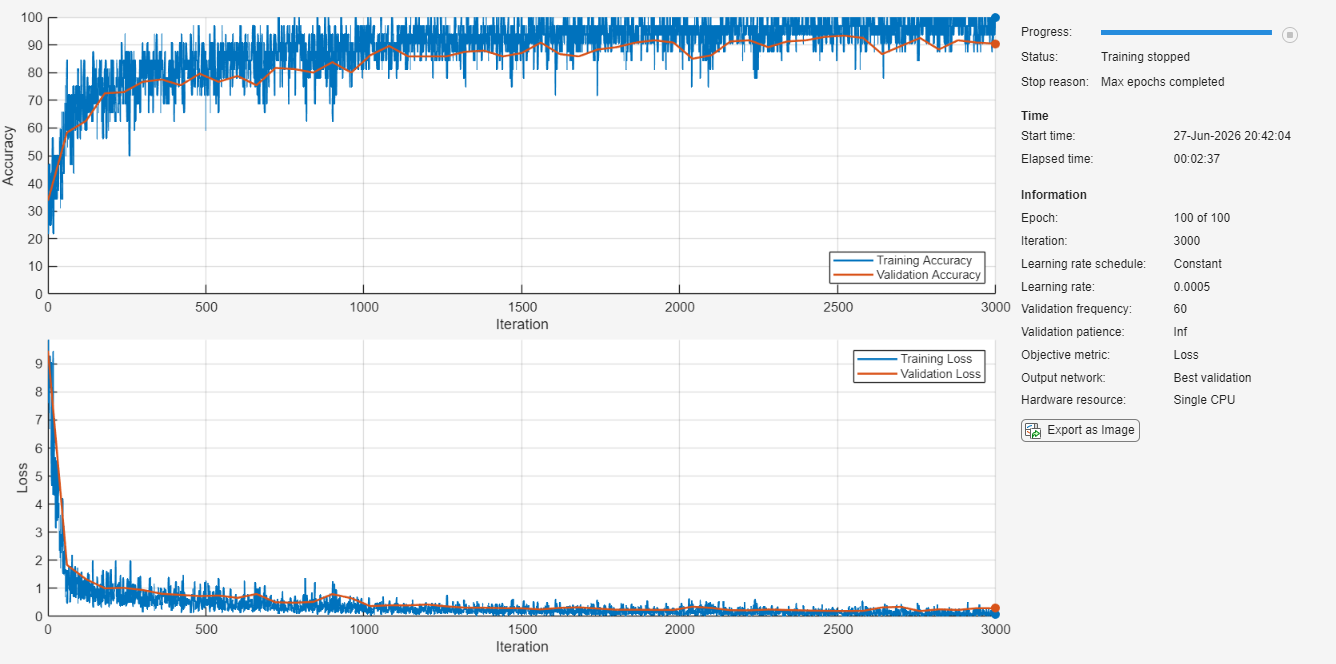

Training Lauf 7 beendet.


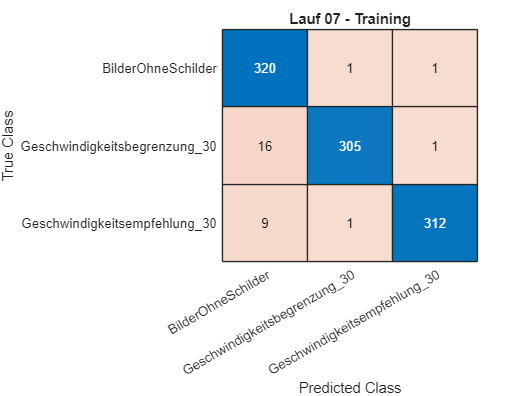

Lauf 7 - Training Accuracy: 97.00%


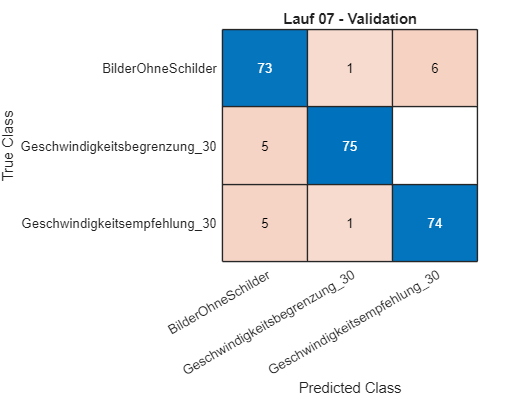

Lauf 7 - Validation Accuracy: 92.50%


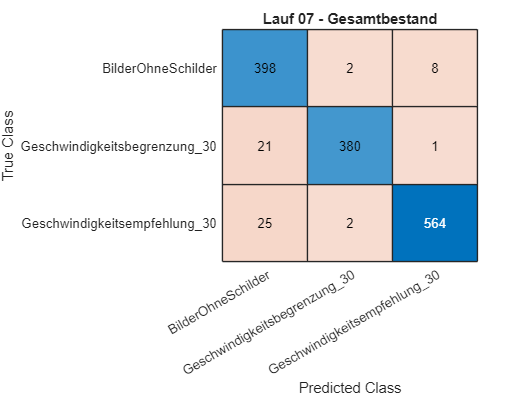

Lauf 7 - Gesamt Accuracy: 95.79%


Lauf 7 - Falsch Training: 29


Lauf 7 - Falsch Validation: 18


Lauf 7 - Falsch Gesamtbestand: 59


ENDE LAUF 7 von 10


START LAUF 8 von 10


Training Lauf 8 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.628                                    33.333
            1        1       00:00:00       0.0005          12.953                                 18.75                      
           50        2       00:00:04       0.0005          1.0701                                    50                      
           60        2       00:00:05       0.0005          1.0011           0.97433              40.625                  52.5
          100        4       00:00:07       0.0005         0.89573                                    50                      
          120        4       00:00:08       0.0005          0.6392           0.77798                62.5       

Training Lauf 8 beendet.


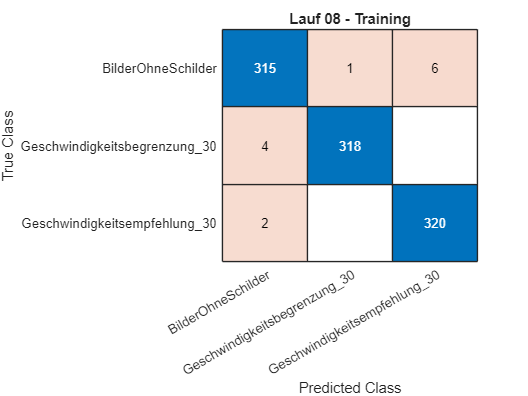

Lauf 8 - Training Accuracy: 98.65%


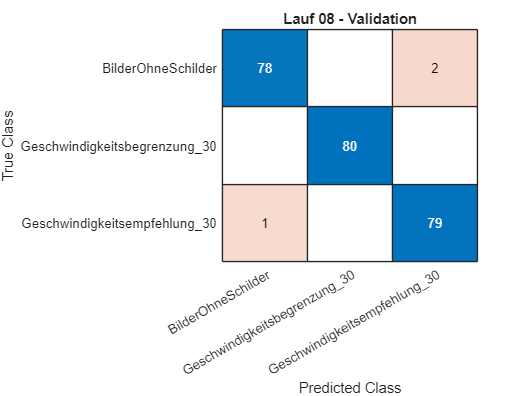

Lauf 8 - Validation Accuracy: 98.75%


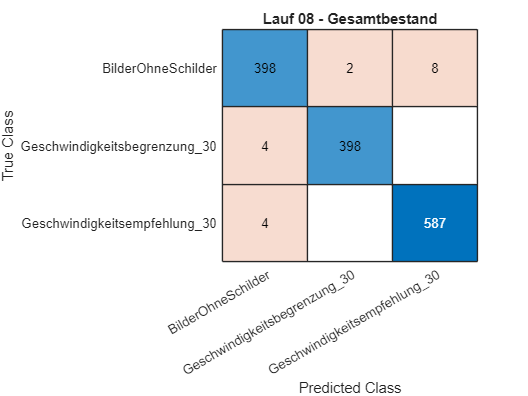

Lauf 8 - Gesamt Accuracy: 98.72%


Lauf 8 - Falsch Training: 13


Lauf 8 - Falsch Validation: 3


Lauf 8 - Falsch Gesamtbestand: 18


ENDE LAUF 8 von 10


START LAUF 9 von 10


Training Lauf 9 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            7.1553                                    29.167
            1        1       00:00:00       0.0005          8.5812                                21.875                      
           50        2       00:00:04       0.0005          2.3514                                 9.375                      
           60        2       00:00:05       0.0005          1.5481            1.8964                37.5                24.167
          100        4       00:00:07       0.0005          1.4679                                53.125                      
          120        4       00:00:08       0.0005         0.88085            1.2168              65.625       

Training Lauf 9 beendet.


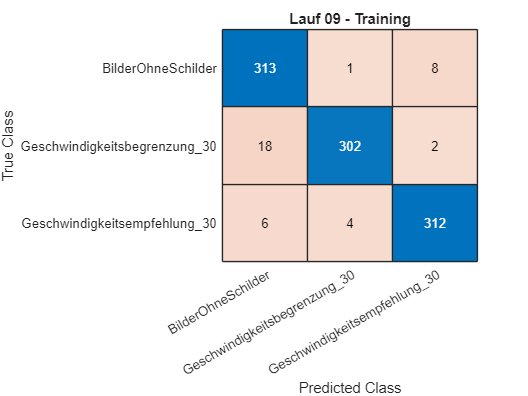

Lauf 9 - Training Accuracy: 95.96%


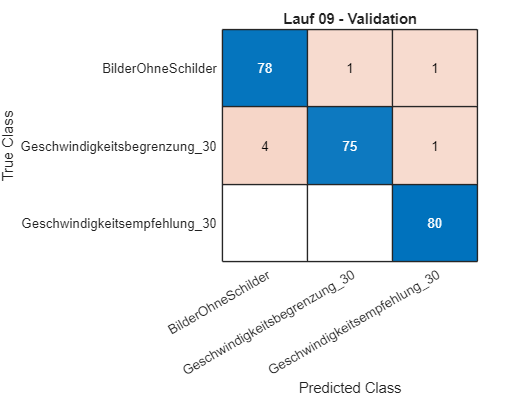

Lauf 9 - Validation Accuracy: 97.08%


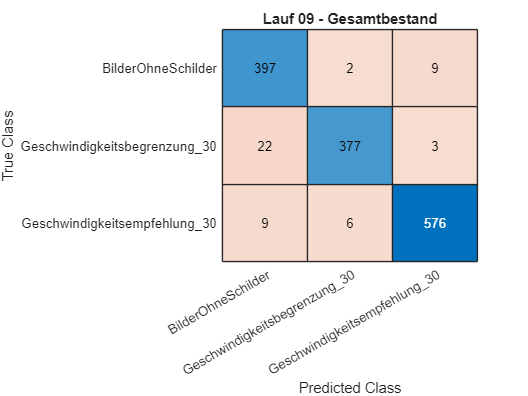

Lauf 9 - Gesamt Accuracy: 96.36%


Lauf 9 - Falsch Training: 39


Lauf 9 - Falsch Validation: 7


Lauf 9 - Falsch Gesamtbestand: 51


ENDE LAUF 9 von 10


START LAUF 10 von 10


Training Lauf 10 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            7.4591                                     38.75
            1        1       00:00:00       0.0005          6.8795                                40.625                      
           50        2       00:00:05       0.0005         0.99408                                  62.5                      
           60        2       00:00:05       0.0005         0.92473           0.94584               56.25                62.083
          100        4       00:00:07       0.0005         0.75067                                59.375                      
          120        4       00:00:08       0.0005         0.68135           0.67083              71.875       

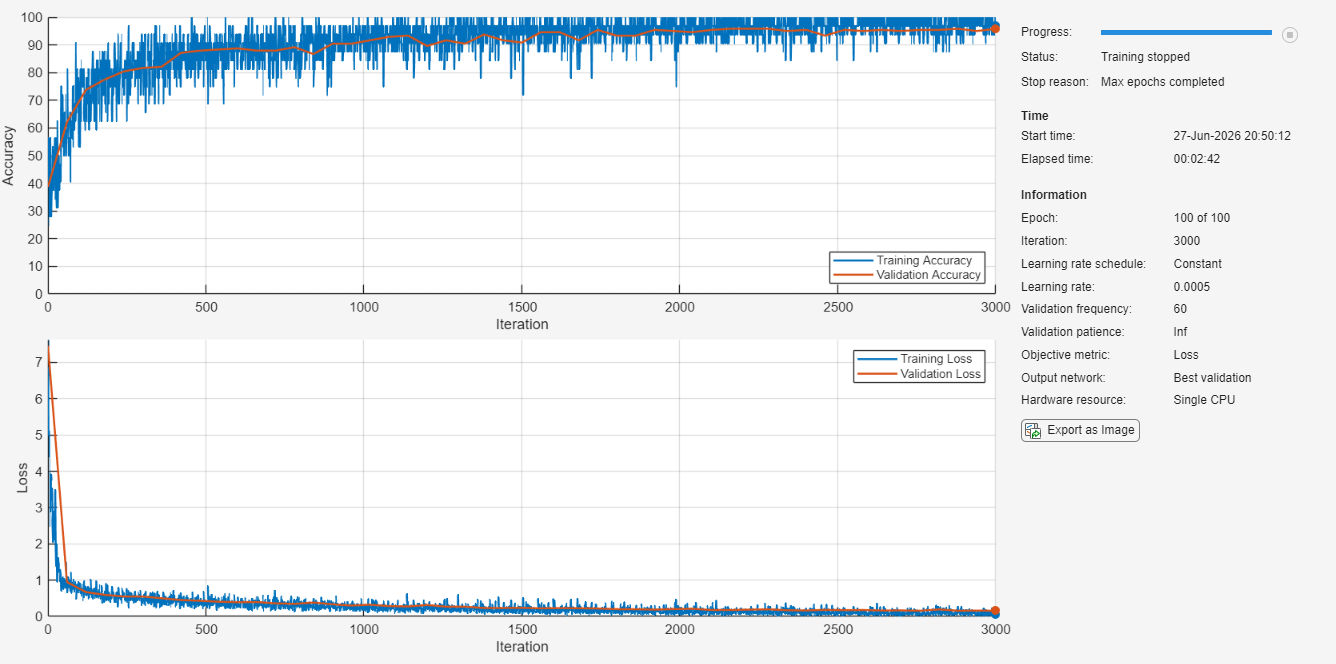

Training Lauf 10 beendet.


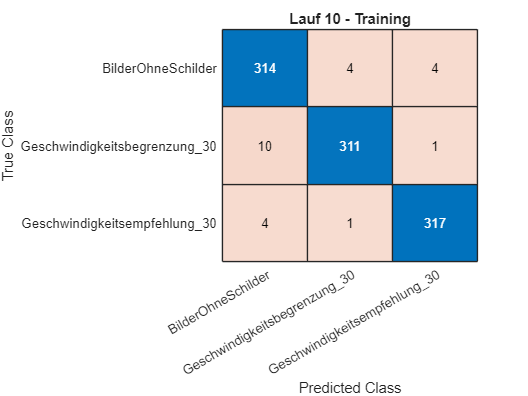

Lauf 10 - Training Accuracy: 97.52%


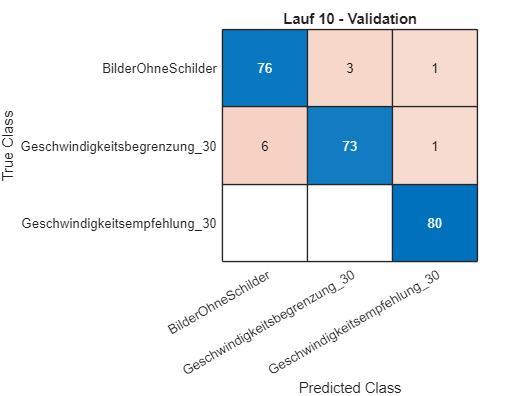

Lauf 10 - Validation Accuracy: 95.42%


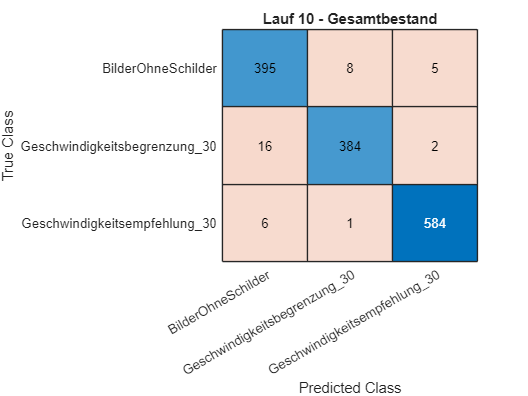

Lauf 10 - Gesamt Accuracy: 97.29%


Lauf 10 - Falsch Training: 24


Lauf 10 - Falsch Validation: 11


Lauf 10 - Falsch Gesamtbestand: 38


ENDE LAUF 10 von 10


    % % Falsch erkannte Trainingsbilder anzeigen
    % for i = 1:length(wrongIdxtrain)
    %     img = readimage(imdsTrain, wrongIdxtrain(i));
    %     figure("Name", sprintf("Lauf %02d - Training falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Training falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
    % end
    % 
    % for i = 1:length(wrongIdxVali)
    %     img = readimage(imdsValidation, wrongIdxVali(i));
    %     figure("Name", sprintf("Lauf %02d - Validation falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Validation falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTest(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
    % end
    % 
    % % Dateinamen der falsch erkannten Gesamtbilder speichern
    % dateiname = imdsSchilder.Files(wrongIdxVali2);
    % 
    % wrongTable = table( ...
    %     repmat(run, numel(wrongIdxVali2), 1), ...
    %     string(dateiname), ...
    %     string(trueLabelsVali2(wrongIdxVali2)), ...
    %     string(YTest2(wrongIdxVali2)), ...
    %     'VariableNames', ["Lauf", "Dateiname", "RichtigesLabel", "Vorhersage"]);
    % 
    % writetable(wrongTable, sprintf("Falsch_Gesamtbestand_Lauf_%02d.csv", run));

    %% Werte dieses Laufs speichern
    RunNr(run) = run;
    TrainAccuracy(run) = accuracyTrain * 100;
    ValidationAccuracy(run) = accuracyVal * 100;
    GesamtAccuracy(run) = accuracyAll * 100;
    AnzahlFalschTrain(run) = numel(wrongIdxtrain);
    AnzahlFalschValidation(run) = numel(wrongIdxVali);
    AnzahlFalschGesamt(run) = numel(wrongIdxVali2);

    results = table(RunNr(1:run), ...
        TrainAccuracy(1:run), ...
        ValidationAccuracy(1:run), ...
        GesamtAccuracy(1:run), ...
        AnzahlFalschTrain(1:run), ...
        AnzahlFalschValidation(1:run), ...
        AnzahlFalschGesamt(1:run), ...
        'VariableNames', ["Lauf", "TrainingAccuracy", "ValidationAccuracy", ...
        "GesamtAccuracy", "FalschTraining", "FalschValidation", "FalschGesamt"]);

    % disp(results)

    % Nach jedem Lauf direkt schreiben, damit nichts verloren geht
    writetable(results, "GAP100_32_Ergebnisse_Einzellaeufe.csv");

    fprintf("ENDE LAUF %d von %d\n", run, numRuns);

end


fprintf("\nAlle Läufe beendet.\n");


Alle Läufe beendet.


disp(results)

    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

      1          98.033               94.583              97.645              19                 13                33     
      2          97.619               94.167              97.145              23                 14                40     
      3          97.101               97.083              96.931              28                  7                43     
      4          97.308               96.667              97.502              26                  8                35     
      5          98.447